# Particle Swarm Optimization

#### Sistemas Inteligentes - Grado en Ingeniería Informática

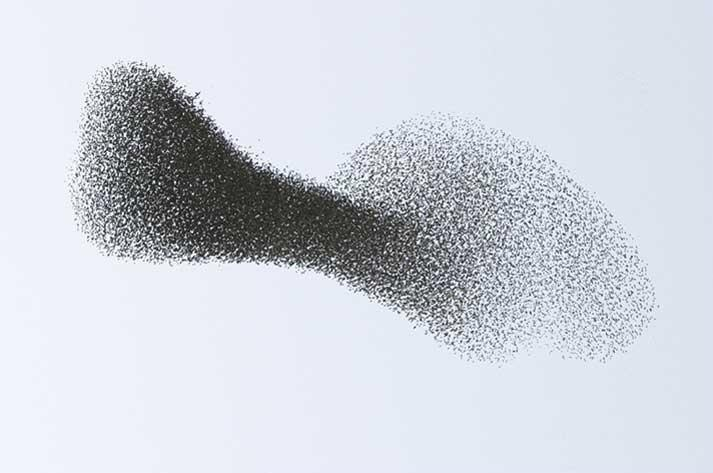

## 1. Introducción

En la optimización basada en enjambre de partículas, cada una de las partículas tiene asignada una posición y una velocidad dentro del espacio de búsqueda. Ambas variables se pueden calcular mediante las siguientes fórmulas:


$$V_i^{k+1}=wV_i^k+c_pr_p(S_{pbest_i}-S_i^k)+c_gr_g(S_{gbest}-S_i^k)$$



$$S_i^{k+1}=S_i^k+V_i^{k+1}$$
 

Donde $S_i^k$ y $V_i^k$ son la posición y velocidad de la partícula i en la iteración k respectivamente, $S_{gbest}$ es la mejor posición global y $S_{pbest_i}$ la mejor posición de la partícula i.

El PSO también tiene una serie de coeficientes que definen cómo se comporta el algoritmo, o cómo se mueve el enjambre en el espacio de búsqueda, estos son: 

- La constante inercial $w$ que establece la influencia de la solución anterior sobre la velocidad de la partícula.

- Las constantes de aceleración $c_p$ y $c_g$ para establecer la influencia de la mejor solución, tanto particular como global.

- Unos números aleatorios $r_p$ y $r_g$ para evitar óptimos locales.

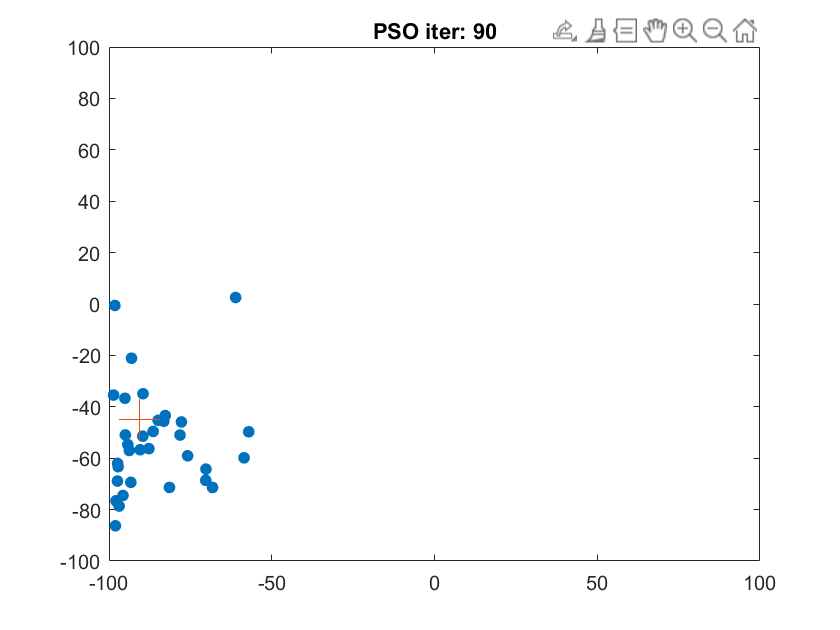

Niter = 90;
N =86;
w = 0.9;
cp = 0.8;
cg = 0.1;
 

f=figure(1);
f.Visible = "on";
%figure('Number', 1, 'Visible',"on")
xlim([-100,100])
ylim([-100,100])

[X,Y]=ginput(2);

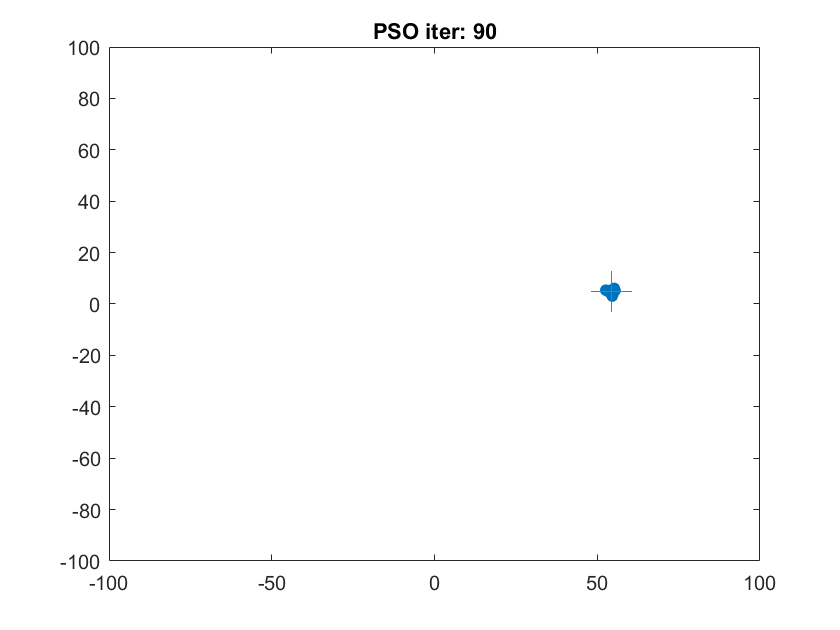

Xstart = X(1);
Ystart = Y(1);

Xend = X(2);
Yend = Y(2);

pos = 20*randn(N,2)+repmat([Xstart Ystart],N,1);
vel = randn(N,2)*0.1;
sol = [Xend,Yend];

feval=sum((pos-sol).^2,2);
pbest=pos;
[~,f]=min(feval);
gbest=pos(f,:);

for iter = 1:Niter
    % Update velocity and location of each particle, i, according to the
    % equation.
    vel = w.*vel + cp.*rand.*(pbest-pos) + cg.*rand.*(repmat(gbest,N,1)-pos);
    pos = pos + vel;
    
    feval1=sum((pos-sol).^2,2);
    feval2=sum((pbest-sol).^2,2);
    
    i = find(feval1<feval2);
    pbest(i,:) = pos(i,:);
    
    [feval1,i] = min(feval1);
    feval2 = sum((gbest-sol).^2,2);
    
    if feval1<feval2
        gbest = pos(i,:);
    end
    
    plot(pos(:,1),pos(:,2),'.', 'MarkerSize', 20)
    hold on
    plot(Xend,Yend,'+', 'MarkerSize', 20)
    hold off
    xlim([-100,100])
    ylim([-100,100])
    title(['PSO iter: ' num2str(iter)])
    drawnow% limitrate
end

## 2. PSO para problemas de permutación de enteros

Cuando tratamos de modelar un problema de permutación de enteros (donde cada solución a un problema sea una permutación de un conjunto de enteros), como puede ser el problema de las N-Reinas, nos preguntamos cómo podemos moderla la posición y la velocidad de una partícula. Tenemos por tanto que definir qué son ambas variables, y las operaciones que se realizan sobre ella, como por ejemplo la suma. 

### 2.1. Posición

La posición de una partícula corresponde a una posible solución al problema. Por lo tanto está constituida por una permutación de los N posibles valores enteros. Por ejemplo para $N=8$


$$S_i=[3, 4, 5, 2, 1, 6, 7, 8]$$


### 2.2. Velocidad

La velocidad en los problemas de permutación de enteros la modelaremos como el conjunto de intercambios que se aplican a una partícula y generan una nueva posición, es decir, a mayor velocidad, mayor número de intercambios.

La velocidad la representaremos como una lista de pares de enteros $(i,j)$ que indican el intercambio a realizar sobre los elementos de $S_i$

Por ejemplo, si aplicamos la velocidad $V=(4, 1)$ a


$$S_i =\left\lbrack \mathbf{3},4,5,\mathbf{2},6,7,8\right\rbrack$$


Obtenemos


$$S_i =\left\lbrack \mathbf{2},4,5,\mathbf{3},6,7,8\right\rbrack$$


### 2.3 Posición + Velocidad

Como hemos creado nuestras propias definiciones de la posición y velocidad de una partícula, también es necesario definir cuál es la suma entre ambas variables, para poder realizar la ecuación $S_i^{k+1}=S_i^k+V_i^{k+1}$ 

En nuestro caso, como la posición es una permutación de valores enteros y la velocidad una lista de intercambios de valores enteros, realizaremos la suma de ambos como la aplicación de esos intercambios sobre una posición determinada. Por ejemplo, siendo $V=\left\lbrack \left(8,1\right)\left(2,2\right)\left(7,3\right)\right\rbrack$ la velocidad de una partícula y $S=\left\lbrack 3,4,5,2,1,6,7,8\right\rbrack$ la posición de la misma. la suman de la posición con la velocidad daría como resultado:


$$\begin{array}{l}
\left\lbrack \mathbf{3},4,5,2,1,6,7,\mathbf{8}\right\rbrack \to \left\lbrack \mathbf{8},4,5,2,1,6,7,\mathbf{3}\right\rbrack \;\left(8,1\right)\\
\left\lbrack 8,\mathbf{4},5,2,1,6,7,3\right\rbrack \to \left\lbrack 8,\mathbf{4},5,2,1,6,7,3\right\rbrack \;\left(2,2\right)\\
\left\lbrack 8,4,\mathbf{5},2,1,6,\mathbf{7},8\right\rbrack \to \left\lbrack 8,4,\mathbf{7},2,1,6,\mathbf{5},3\right\rbrack \;\left(7,3\right)
\end{array}$$


### 2.3 Posición - Posición

Para calcular el nuevo valore de velocidad es necesario definir la diferencia entre distintas posiciones ( $S_{pbest_i}-S_i^k$, $S_{gbest}-S_i^k$). Al ser la posición de una partícula una permutación de enteros, la diferencia entre ambas serán los movimientos necesarios para poder pasar de una posición a otra. Por lo tanto la diferencia entre ambas posiciones devolverá una lista de pares de intercambios sobre $S_i^{\;k}$

Por ejemplo si tenemos las posiciones $S_k =\left\lbrack 3,4,5,2,1,6,7,8\right\rbrack$ y $S_j =\left\lbrack 2,4,5,7,1,6,8,3\right\rbrack$ la diferencia entre ambas posiciones será $\left\lbrack \left(7,8\right)\left(4,7\right)\left(1,4\right)\right\rbrack$ porque si se realizan esos intercambios sobre $S_j$ se obtiene $S_k$


$$\begin{array}{l}
\left\lbrack 2,4,5,7,1,6,\mathbf{8},\mathbf{3}\right\rbrack \to \left\lbrack 2,4,5,7,1,6,\mathbf{3},\mathbf{8}\right\rbrack \;\left(7,8\right)\\
\left\lbrack 2,4,5,\mathbf{7},1,6,\mathbf{3},8\right\rbrack \to \left\lbrack 2,4,5,\mathbf{3},1,6,\mathbf{7},8\right\rbrack \;\left(4,7\right)\\
\left\lbrack \mathbf{2},4,5,\mathbf{3},1,6,7,8\right\rbrack \to \left\lbrack \mathbf{3},4,5,\mathbf{2},1,6,7,8\right\rbrack \;\left(1,4\right)
\end{array}$$


### 2.4 Velocidad + Velocidad

Finalmente, la suma de dos velocidad, al ser una velocidad una lista de pares de intercambios, será la aplicación sucesiva de diferentes movimientos de intercambio. La suma consiste en ir solapando los pares de las listas de dichas velocidades, de manera que se obtiene una nueva lista de pares. Para que se produzca un nuevo par, deben coincidir los valores final e inicial de los pares involucrados, es decir, los pares $\left(i,j\right)$ y $\left(j,k\right)$ se solapan formando el par $\left(i,k\right)$. En el caso de que dos pares no se solapen, el resultado será el primer par y si las listas son de distinto tamaño, la completaremos con la de mayor longitud. Por ejemplo, si tenemos las velocidades $V_k =\left\lbrack \left(1,1\right)\left(2,5\right)\left(5,4\right)\left(1,3\right)\right\rbrack$ y $V_j =\left\lbrack \left(2,2\right)\left(5,1\right)\left(4,3\right)\left(2,4\right)\right\rbrack$ la suma de ambas será $V_k +V_j =\left\lbrack \left(1,1\right)\left(2,1\right)\left(5,3\right)\left(1,3\right)\right\rbrack$.

### 2.5 Coeficiente * Velocidad

Por último, definiremos la operación de multiplicación de un coeficiente por una velocidad, como la probabilidad de elergir alguno de los términos que definen la velocidad. Por ejemplo, sea $V=\left\lbrack \left(1,8\right)\left(2,6\right)\left(4,3\right)\right\rbrack$, entonces $0\ldotp 5*V$ significará que se escoge con probabilidad 0.5 cada una de los pared de la velocidad. Para ello se crea una secuencia de números aleatorios (ej. [$0\ldotp 2,0\ldotp 5,0\ldotp 8$]) y se escogen aquellos pares que correspondan con los valores de la secuencia de números aletarorios que superen el valor del coeficiente. En este caso $0\ldotp 5*V=\left\lbrack \left(4,3\right)\right\rbrack$, por lo que solo se aplica el intercambio $\left(4,3\right)$ cuyo valor aleatorio es 0.8 superando el valor del coeficiente 0.5.

## 3 PSO y las N-Reinas

A continuación realizaremos la implementación del algoritmo de PSO para resolver el problema de las N-Reinas. En primer lugar, vaya a la sección **3.1** y complete las funciones auxiliares para el funcionamiento del código, vuelva a esta sección.

clear variables
close all
clc

NReinas=10;
NTableros=40;
MAX_ITERACIONES=2000;
MAXFITNESS=sum(1:NReinas-1);

cp =0.3;    % aceleración hacia la local
cg =0.7;    % aceleración hacia la global
w  =0.4;     % influencia de la solución previa

 

#### Genera poblacion (posiciones) y velocidades

poblacion=generaTableros(NReinas,NTableros);
velocidades= cell(NTableros,1);  %% cada individuo puede tener más o menos velocidades

#### Evaluacion de los tableros

fitness=EvaluaPoblacion(poblacion);

#### Calcula pbest y gbest

[val,ind]=max(fitness);
gbest=[poblacion(ind,:),fitness(ind)];
pbest=[poblacion,fitness];

#### Proceso iterativo

Comienza el proceso iterativo de búsqueda. **Completa el siguiente bloque de código con el resto de condiciones de parada**.

itera=1;
while (itera<=MAX_ITERACIONES) && gbest(end)< MAXFITNESS%% COMPLETAR resto de condiciones
    for individuo=1:NTableros

En primer lugar calculamos la velocidad para cada uno de los individuos


$$V_i^{k+1}=wV_i^k+c_pr_p(S_{pbest_i}-S_i^k)+c_gr_g(S_{gbest}-S_i^k)$$
       

        Vi=velocidades{individuo}; 

ans = 42

        Vi=multiplica(w,Vi);

itera = 2001

        
        Errp=sustraeTableros(poblacion(individuo,:),pbest(individuo,1:NReinas));
        Errg=sustraeTableros(poblacion(individuo,:),gbest(1:NReinas));

Calculamos el número de intercambios (velocidades) que se cogerán de cada tipo

        cprp=cp*rand;
        cgrg=cg*rand;
        Vp=multiplica(cprp,Errp);
        Vg=multiplica(cgrg,Errg);        

Suma de las velocidades $V_i +V_p +V_g$

        Vtotal=sumaVelocidades(Vi,Vp);
        Vtotal=sumaVelocidades(Vtotal,Vg);

Suma de la velocidad a la posicion actual

        poblacion(individuo,:)=aplicaVelocidad(poblacion(individuo,:),Vtotal);

Se guardan los pares de Vtotal en la celda velocidades

        if ~isempty(Vtotal)
           velocidades{individuo,1}=Vtotal;
        end          
        f=EvaluaTablero(poblacion(individuo,:));

**Actualiza a continuación los mejores valores de fitness a nivel local y global**

        %%%%%%%%%% COMPLETAR
        [val,ind]=max(f);
        if val > gbest(end)
            gbest=[poblacion(individuo,:),f(ind)];
        end
        if fitness(individuo) < f
            pbest(individuo,:)=[poblacion(individuo,:),f];
        end
        %%%%%%%%%%

    end %% for
    itera=itera+1;
end   
gbest(end)
itera

### 3.1 Funciones auxiliares

A continuación se definen una serie de funciones que servirán para el correcto funcionamiento del algoritmo.

#### Función para generar tableros

function poblacion=generaTableros(NReinas, NTableros)
    poblacion = zeros(NTableros, NReinas);
    for i=1:NTableros
        poblacion(i,:)=randperm(NReinas); 
    end
end

#### Función para evaluar un tablero

La función EvaluaTablero debe recorrer el tablero y no encontrar 2 reinas en la misma fila, columna y diagonal. Si el operador aplicado es el intercambio colisiones en filas y columnas nunca se producirán, por tanto las importantes son en diagonal. Suponiendo que cada Reina ocupa una columna diferente, se suman las colisiones en diagonal y en fila

function r=EvaluaTablero(V)
    r=0;
    for i=1:length(V)-1
        for j=i+1:length(V)
             r=r+ (abs(V(i)-V(j))==abs(i-j))+(V(i)==V(j));
        end
    end
    
    %%% Maximización del problema, 
    
    r=-1*r;  %% Maximiza el problema, pero además en ciertos problemas los valores deben ser positivos, 
             %% por tanto le sumamos el número mñaximo de ataques posibles,
             %% así 0 conflictos significa la máxima evaluación
                
    maxAtaques=sum(1:length(V)-1);
    r=maxAtaques+r;
end

#### Función para evaluar la población

function e=EvaluaPoblacion(V)
    for i=1:length(V)
        e(i,:)=EvaluaTablero(V(i,:));
    end  
end


#### Función para sustraer dos tableros (posiciones)

function intercambios=sustraeTableros(t2,t1)
    %% numero de diferencias existentes entre 2 tableros
    %% intercambios guarda la información necesaria para convertir t1 en t2
    N=length(t1);
    diferencia=(t1==t2);
    i=N;
    k=1;
    intercambios=[];
    taux=t1;
    j=1;  %% inicialización para que funcione el código
    while (sum(diferencia)~=N  && i >= 1)
        if ~diferencia(i)
            %%%%%%%%%%%%%%%%%%%%%%%
            %%%%%% COMPLETAR %%%%%%
            j = find(taux == t2(i));
            %%%%%%%%%%%%%%%%%%%%%%%
            taux([i,j]) = taux([j,i]);
            intercambios(k,:)=[i,j];
        end
        i=i-1;
    end
end


#### Función para la suma de dos velocidades.

function V=sumaVelocidades(V1,V2)
    %%% (1,2) + (2,3) = (1,3)
    l1=size(V1,1);
    l2=size(V2,1); %% longitudes de ambas listas
    i=1;
    V=[];
    while ((i<=l1) && (i<=l2))
        a = V1(i,:);
        b = V2(i,:);
        if a(2) ==b(1) %%TRANSITIVO
            %%%%%%%%%%%%%%%%%%%%%%%
            %%%%%% COMPLETAR %%%%%%
            V(i,:) =[a(1) b(2)]; 
            %%%%%%%%%%%%%%%%%%%%%%%
        else
            %% si no transitiva se copia la primera
            %%%%%%%%%%%%%%%%%%%%%%%
            %%%%%% COMPLETAR %%%%%%
            V(i,:) = a;
            %%%%%%%%%%%%%%%%%%%%%%%
        end
        i=i+1;
    end
    %% resto de elementos de cada lista se copian tal cual
    if (i<=l1)
        V(i:l1,:)=V1(i:end,:);
    else
        if (i<=l2)
           V(i:l2,:)=V2(i:end,:);
        end
    end
end

#### Función para multiplicar un coeficiente con una velocidad

function Vnew=multiplica(r,V)
    N=size(V,1);
    Vnew=[];
    if N>0
        %% generamos aleatorios por cada intercambio en V
        %% escogemos los que superen el valor r
        indices=1; %% inicializado para que funcione el codigo
        %%%%%%%%%%%%%%%%%%%%%%%
        %%%%%% COMPLETAR %%%%%%
        numAleatorios = rand(N,1)';
        indices=find(numAleatorios >r);
        %%%%%%%%%%%%%%%%%%%%%%%
        if ~isempty(indices)
            Vnew=V(indices,:);  %% elegimos 
        end
    end
end


#### Función para aplicar la velocidad a una posición

function t=aplicaVelocidad(S,V)
    t=S;
    %%%%%%%%%%%%%%%%%%%%%%%
    %%%%%% COMPLETAR %%%%%%
    N = size(V,1);
    for i=1:N
        a = V(i,:);
        
        val1 = t(a(1));
        val2 = t(a(2));
        t(a(1)) = val2;
        t(a(2)) = val1;
    end
    %%%%%%%%%%%%%%%%%%%%%%%
end